LLN_st.name='LLN'; 
LLN_st.lat=23.4686;
LLN_st.lon=120.8736;
LLN_st.alt=2862;
LLN_st.env='Mt';
LLN_st.footp='F';


LLN_rd2=read_betsy('LLN_2008_2018_new',LLN_st.name);

LLN_rd=read_betsy('LLN_2008_2018_new_longformat',LLN_st.name);

datevec(LLN_rd.Time(1))

ans =         2008          10          11           0           0           0


datevec(LLN_rd.Time(end))

ans =         2019           1           1           0           0           0


prctile(LLN_rd.U0_S11,[5 50 95])

ans =     5.6000   16.6500   44.4000


prctile(LLN_rd.U1_S11,[5 50 95])

ans =     5.4500   16.4000   44.0400


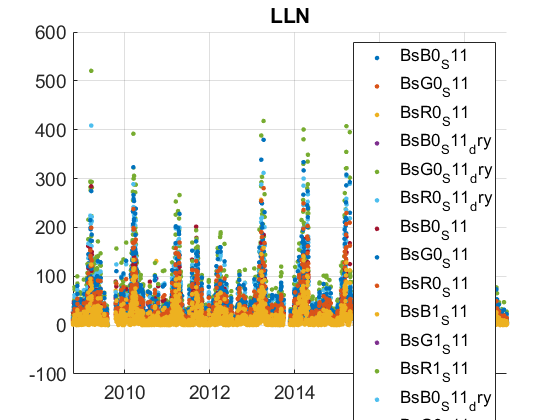

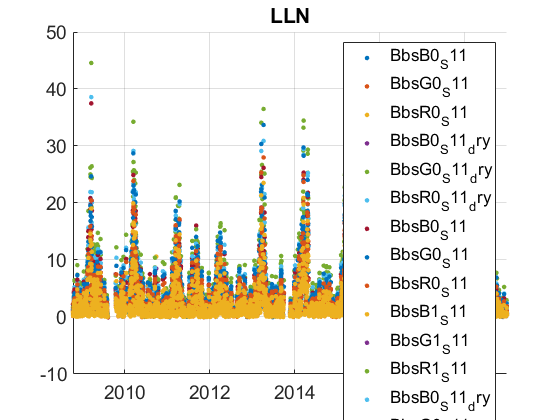

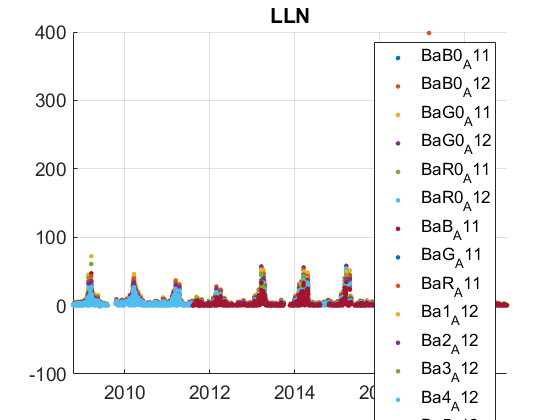

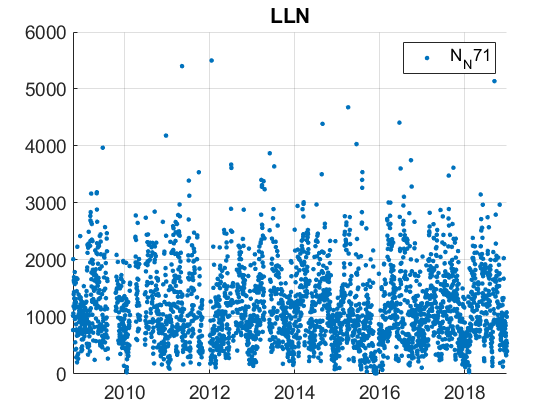

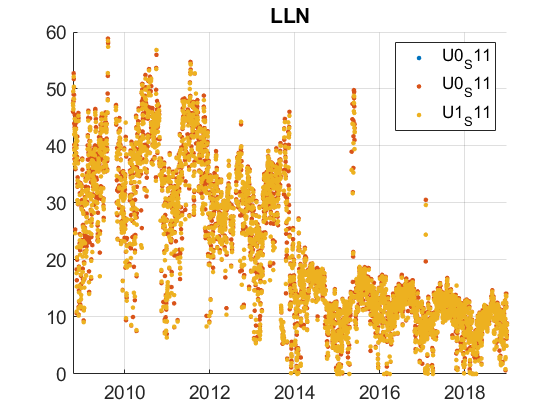

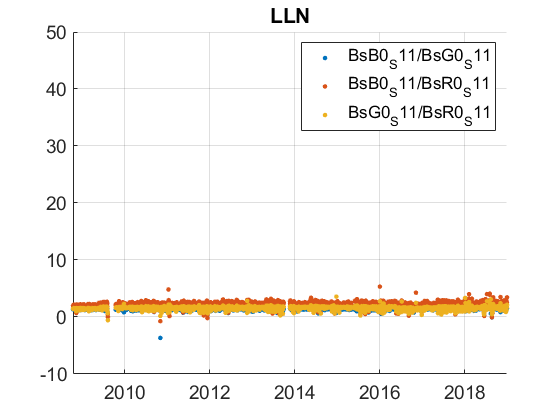

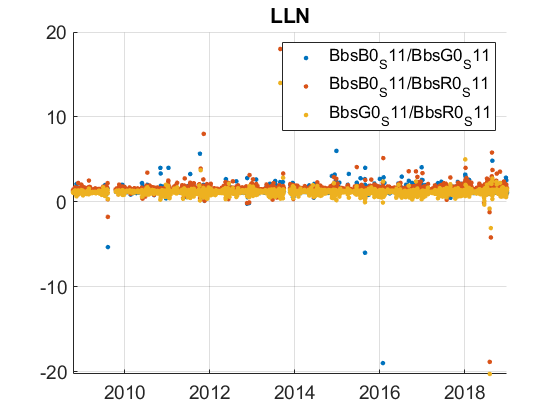

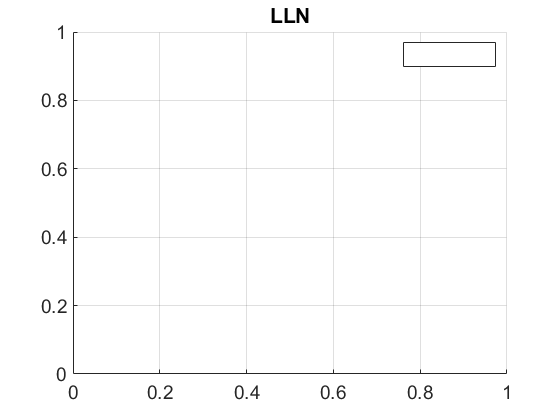

plotFigControl(LLN_rd,LLN_st.name);

% 2 size cut, ok
% sc: ok, a double seasonality with max in spring and second max, lower, in autumn, no negatives
% abs: 2 size cut, a double seasonality with max in spring and autumn,, no negatives
%SSA: seasonal cycle with min in winter. low values : max=0.95

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
lambdaAE7=[370 470 520 590 660 880 950];
LLN_cal=compute_exp_SSA(LLN_rd,lambdaSC, lambdaAE);

SCexclus = 0

ans = 0

ans = 3735

ans = 0

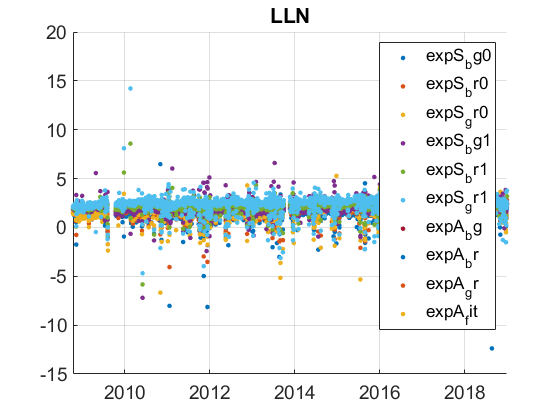

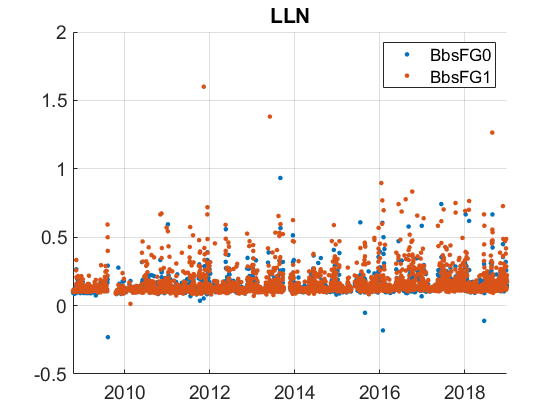

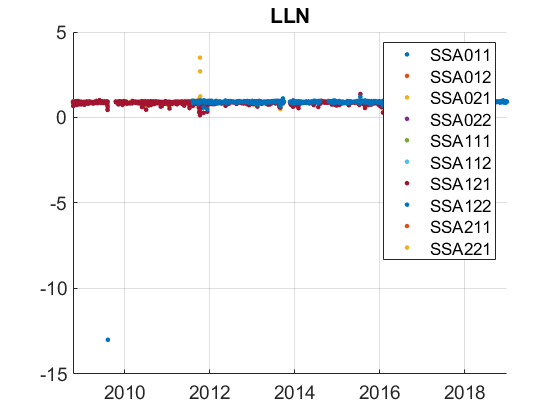

plotFigControl_cal(LLN_cal, LLN_st.name);

%Questions:
%problems:

%scat: The ratio between scattering coefficient G/R and B/R is lower in the first part of 2009 and is abruptally lower in mid-may 2016
%scat: the problem at the beginning of 2009 is also visible in the backscattering G/R and in the exponent involving the red wavelenght
% scat exponent the blue-green exponent is too high at the beginning of 2009, then it decreases abruptly before to increase until 2018

%abs: no absorption data since July and 2018: there is CLAP now
%abs ratio has a clear seasonality with max in spring
% abs: there is a too high number of exponent =0
% SSA: value too high (> 1) in Sept-Oct 2011. Are they bad data to invalidate ?

%N: values lower than usual at the end of 2015

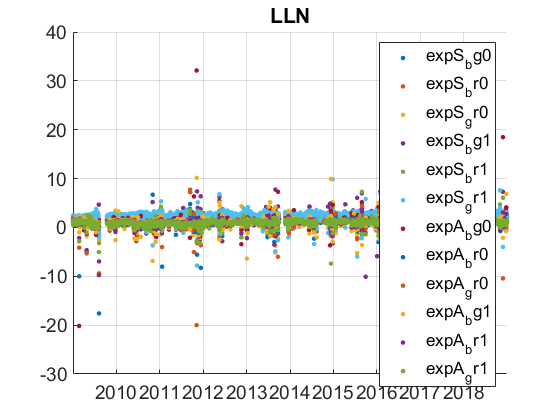

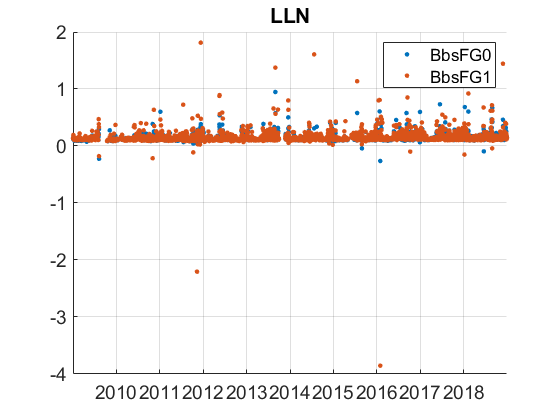

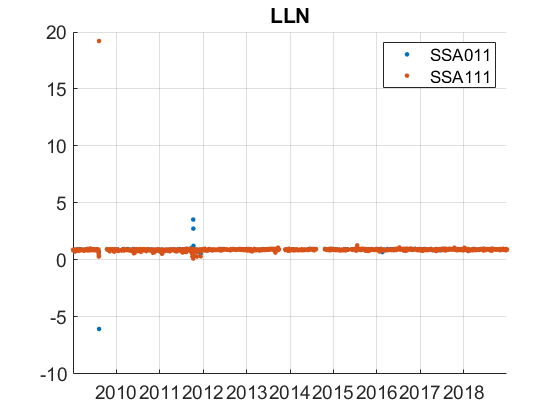

LLN_tr=LLN_rd;
LLN_tr.y=year(LLN_tr.Time);
% begin at the beginning of a year: 2009
%end: 2018
P=timerange('2009-01-01','2019-01-01');
LLN_tr=LLN_tr(P,:);

%ba... without 0 or 1 have no data: remove
%also no AE data Ba1 to Ba7
names=fieldnames(LLN_tr);
c=startsWith(names,["T1";"T0";"T_";"P_";"P0";"P1";"N";"BaB_";"BaG_";"BaR_";"Ba1_";"Ba2_";"Ba3_";"Ba4_";"Ba5_";"Ba6_";"Ba7_";])==1 | endsWith(names,'_dry');
N=names(c);
for i=1:length(N)
    LLN_tr.(N{i})=[];
end

%problem with RH that decreases at the end of 2013 (rupture)
%compute trend in RH, but not in dry (no sense)
%make one time serie with PSAP and CLAP: change in 2012

p1=timerange('2012-01-01','2019-01-01');
LLN_tr.BaB0_A11(p1)=LLN_tr.BaB0_A12(p1);
LLN_tr.BaG0_A11(p1)=LLN_tr.BaG0_A12(p1);
LLN_tr.BaR0_A11(p1)=LLN_tr.BaR0_A12(p1);
LLN_tr.BaB1_A11(p1)=LLN_tr.BaB1_A12(p1);
LLN_tr.BaG1_A11(p1)=LLN_tr.BaG1_A12(p1);
LLN_tr.BaR1_A11(p1)=LLN_tr.BaR1_A12(p1);
%delete other data
LLN_tr.BaB0_A12=[];
LLN_tr.BaG0_A12=[];
LLN_tr.BaR0_A12=[];
LLN_tr.BaB1_A12=[];
LLN_tr.BaG1_A12=[];
LLN_tr.BaR1_A12=[];

LLN_cal2=compute_exp_SSA(LLN_tr,lambdaSC,lambdaAE);

plotFigControl_cal(LLN_cal2, LLN_st.name);

LLN_tr=outerjoin(LLN_tr, LLN_cal2);
LLN_tr.expA_bg1=real(-log(LLN_tr.BaB1_A11./LLN_tr.BaG1_A11)/log(lambdaAE(1)/lambdaAE(2)));
% use  green and expA bg
%compute abs and SSA trends only on G, the longest time series
LLN_tr.BaB0_A11=[];
LLN_tr.BaB1_A11=[];
LLN_tr.BaR0_A11=[];
LLN_tr.BaR1_A11=[];

LLN_tr.BsB0_S11=[];
LLN_tr.BsR0_S11=[];
LLN_tr.BsB1_S11=[];
LLN_tr.BsR1_S11=[];
LLN_tr.BbsB0_S11=[];
LLN_tr.BbsR0_S11=[];
LLN_tr.BbsB1_S11=[];
LLN_tr.BbsR1_S11=[];

LLN_tr.expA_br0=[];
%LLN_tr.expA_br1=[];
LLN_tr.expA_gr0=[];
%LLN_tr.expA_gr1=[];

LLN_tr.expS_br0=[];
LLN_tr.expS_br1=[];
LLN_tr.expS_gr0=[];
LLN_tr.expS_gr1=[];


LLN_result=all_trend_STN(LLN_tr,LLN_st);
plot_10y_in_two(LLN_result,LLN_st);

LLN_result_D=LLN_result;